# Interpolate Height ratio

In this script, we quantify the ratio of bird flying at windturbine height (~50-100m) and compute a ratio of the bird density flying at this altititude bin. 

Load data

load('../2018/data/dc_corr')
load('../2018/data/BelowRadarMPS.mat');
load('../2018/data/Density_estimationMap','g');

Define standar windturbine height

%windturbine_height = 77; %m a.g.l, mean of windturbine hub in dataset
windturbine_maxheight = 100;
windturbine_minheight = 50;

Get bird density integrated over entire height and windturbine height with and without the interpolation

denss_wt = nan(numel(dc(1).time),numel(dc),2); 
denss_tt = nan(numel(dc(1).time),numel(dc),2);
for i_d=1:numel(dc)
    
    % bin height to integrate the full profile (0-200)
    tmp_tt = min(max(dc(1).alt+100-dc(i_d).heightDEM,0),200);
    % bin height to integrate the over windturbine height
    tmp1 = min(max((dc(i_d).heightDEM+windturbine_maxheight) - (dc(1).alt-100),0),200);
    tmp2 = min(max((dc(i_d).heightDEM+windturbine_minheight) - (dc(1).alt-100),0),200);
    tmp_wt = tmp1 - tmp2;
    
    % without simulation (no data => 0)
    tmp4 = dc(i_d).dens4;
    tmp4(:,1:dc(i_d).scatter_lim-1) = nan;
    
    denss_tt(:,i_d,1) = nansum(tmp4 .* tmp_tt,2); % bird/km^3 * m
    denss_wt(:,i_d,1) = nansum(tmp4 .* tmp_wt,2); % bird/km^3 * m

    %  with MPS simulation
    tmp4(:,1:dc(i_d).scatter_lim-1) = mean(MPS{i_d}(:,1:dc(i_d).scatter_lim-1,:),3);
    denss_tt(:,i_d,2) = nansum(tmp4 .* tmp_tt,2);
    denss_wt(:,i_d,2) = nansum(tmp4 .* tmp_wt,2);
end

Some other variable to compute for later

NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;
ratio=denss_wt(:,:,2)./denss_tt(:,:,2);
ratio_s=denss_wt(:,:,2)./denss_tt(:,:,2);

## How many radar are covering windturbine height?

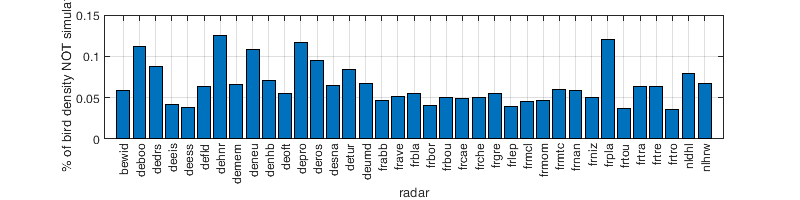

figure('position',[0 0 800 200]); hold on;
bar(nanmean(ratio,1));
xticks(1:numel(dc)); xticklabels({dc.name}); xtickangle(90)
xlabel('radar'); ylabel('% of bird density NOT simulated'); box on; grid on;

**How much bird are flying over wind-turbine height?**

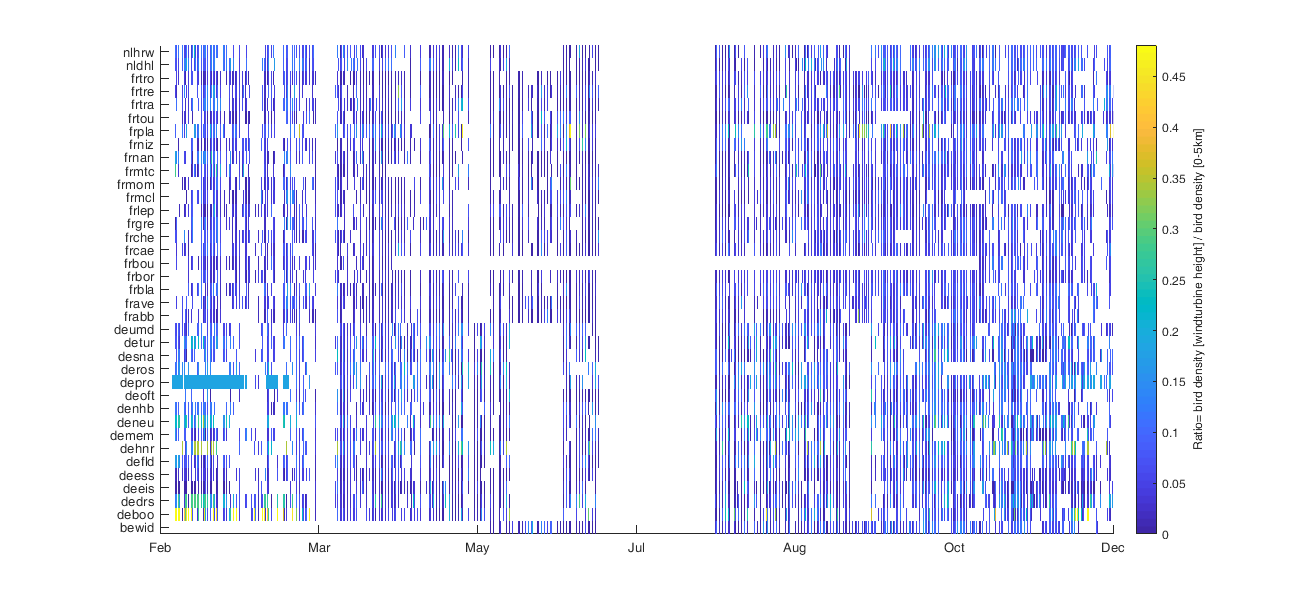

figure('position',[0 0 1300 600]); hold on;
imagesc(datenum(dc(1).time),1:numel(dc),ratio', 'AlphaData',double(0~=denss_tt(:,:,2)'));
axis tight; view(2); yticks(1:numel(dc)); yticklabels({dc.name}); %xtickangle(90)
datetick('x','keepticks'); c=colorbar; c.Label.String='Ratio= bird density [windturbine height] / bird density [0-5km]';

Group per day to see more easily

tmp=dateshift(dc(1).time,'start','day','nearest');
[day_id,day]=findgroups(datenum(tmp));
G = findgroups(day_id);
denss_wt_d = splitapply(@nanmean,denss_wt(:,:,2),G');
denss_tt_d = splitapply(@nanmean,denss_tt(:,:,2),G');

## Temporal and radar variation of the ratio per day

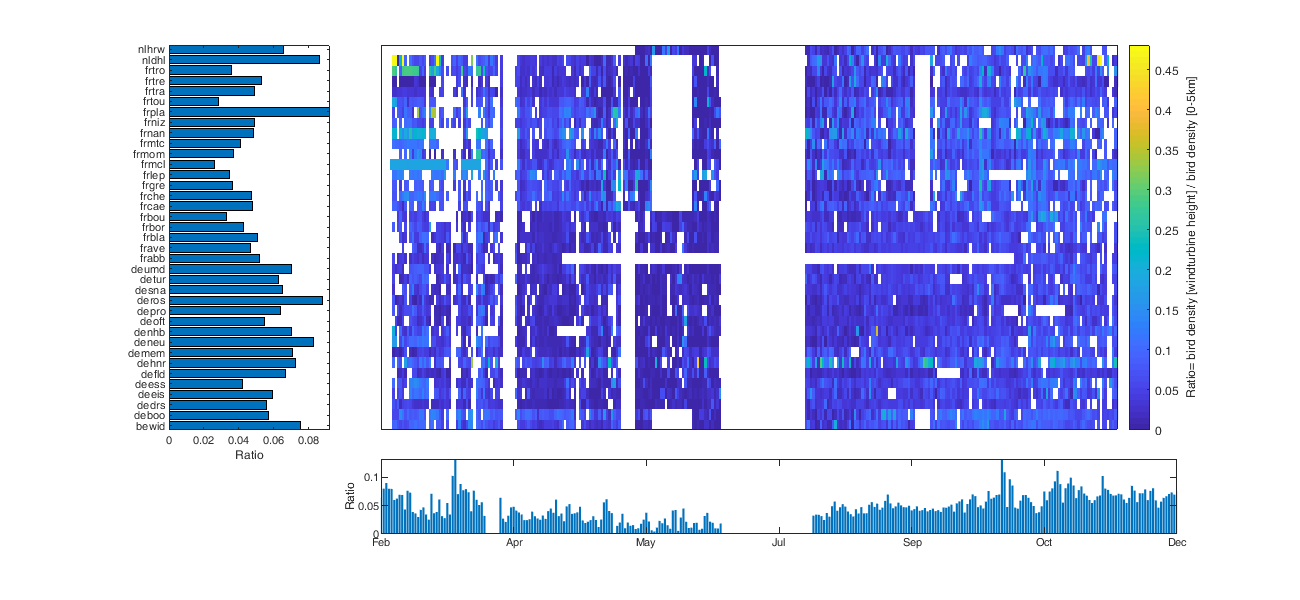

figure('position',[0 0 1300 600]); hold on;
subplot(5,5,[2 20])
imagesc(datenum(dc(1).time),1:numel(dc),(denss_wt_d./denss_tt_d)', 'AlphaData',double(0~=denss_tt_d'));
c=colorbar; c.Label.String='Ratio= bird density [windturbine height] / bird density [0-5km]';
view(2); datetick('x','keepticks'); %xtickangle(90) colorbar; 
xticks([]); yticks([]);
subplot(5,5,[1 16]);
barh(nansum(denss_wt(:,:,2))./nansum(denss_tt(:,:,2)))
yticks(1:numel(dc)); yticklabels({dc.name}); axis tight;xlabel('Ratio')
subplot(5,5,[22 25]);
bar(nansum(denss_wt_d,2)./nansum(denss_tt_d,2)); axis tight; ylabel('Ratio')
datetick('x','keepticks');

## Spatial variation of the ratio

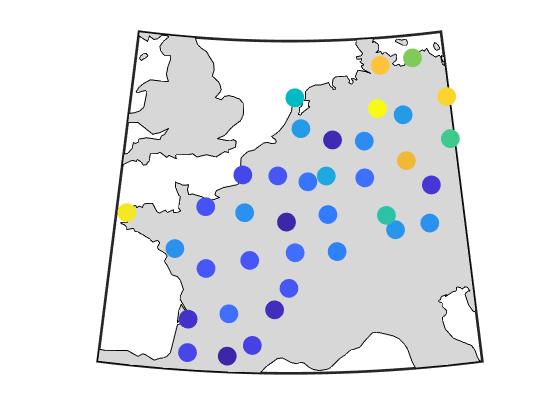

figure;
h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); %geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],200,nanmean(ratio),'filled')

## Intra-night variation

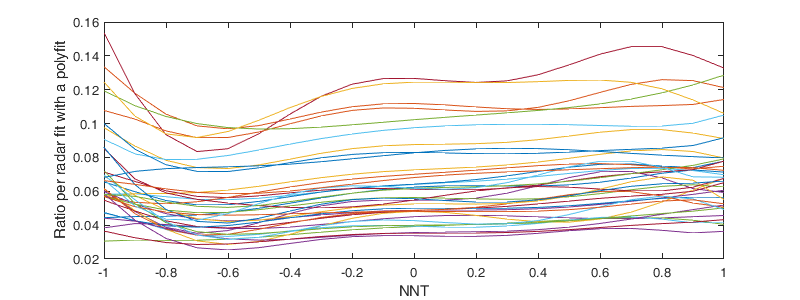

figure('position',[0 0 800 300]); hold on;
p_=8; p=nan(p_,numel(dc));
for i_d=1:numel(dc)
    p(:,i_d)=polyfit(NNT(~isnan(ratio(:,i_d)),i_d),ratio(~isnan(ratio(:,i_d)),i_d),p_-1);
    plot(-1:.1:1,polyval(p(:,i_d),-1:.1:1))
end
xlabel('NNT'); ylabel('Ratio per radar fit with a polyfit'); box on;

As a function of density

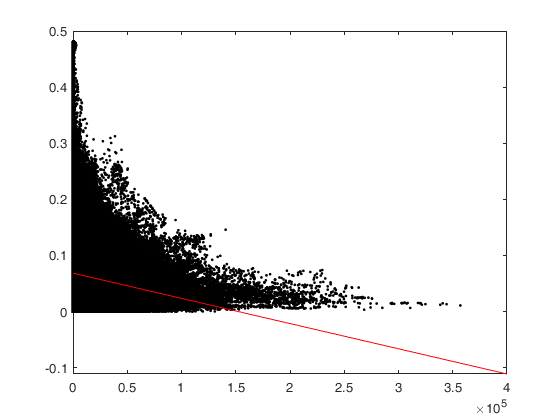

figure;
plot(reshape(denss_tt(:,:,2),1,[]),ratio(:),'.k');a=lsline; a.Color='r';

## Scatter Interpolant

% load('../2018/data/Density_estimationMap','g');

% ratio_coord_time = 13;
% 
% time_data_day=datenum(dateshift(dc(1).time,'start','day','nearest'));
% [day_id,day]=findgroups(time_data_day);
% 
% time_grid_day=datenum(dateshift(g.time,'start','day','nearest'));
% ratio_imterp = nan(g.nlat,g.nlon,g.nt);
% for i=1:numel(day)
%     datetime(day(i),'ConvertFrom','datenum');
%     id = day_id==i;
%     v=denss_wt(id,:,2)./denss_tt(id,:,2);
%     lat = repmat([dc.lat],sum(id),1);
%     lon = repmat([dc.lon],sum(id),1);
%     t = repmat(datenum(dc(1).time(id))',1,numel(dc));
%     Fnn = scatteredInterpolant(lat(~isnan(v)),lon(~isnan(v)),t(~isnan(v)).*ratio_coord_time,v(~isnan(v)),'natural','nearest');
%     ratio_imterp(:,:,time_grid_day == day(i)) = Fnn({g.lat,g.lon,datenum(g.time(time_grid_day == day(i)))});
% end

## GLM

Look at the histogram for determining the link function

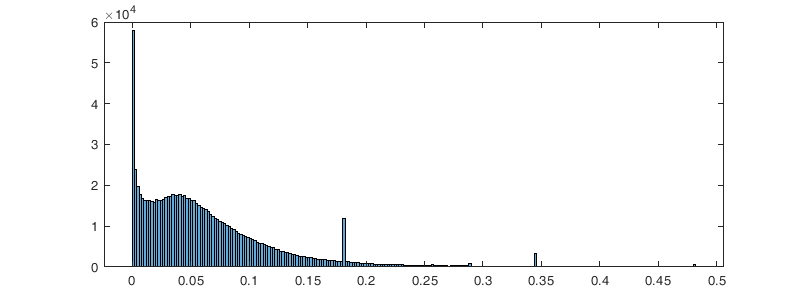

figure('position',[0 0 800 300]); histogram(ratio)

Construct the table for fitting

Tfit = table(ratio(:), ...
    repelem([dc.lat]',numel(dc(1).time),1), ...
    repelem([dc.lon]',numel(dc(1).time),1), ...
    NNT(:) , ...
    repmat(datenum(dc(1).time-dc(1).time(1))',numel(dc),1),...
    reshape(denss_tt(:,:,2),[],1),...
    'VariableNames',{'ratio','lat','lon','NNT', 'time','dens_tt'});

remove nan for the fitting

Tfit(isnan(Tfit.ratio),:)=[];
Tfit(Tfit.NNT>1|Tfit.NNT<-1,:)=[];

Learn the GLM model

% mdl = fitglm(Tfit, 'ratio ~ lat + lon + NNT + NNT^2 + NNT^3 + NNT^4 + time + time^2 + time^3 + time^4')
mdl = fitglm(Tfit, 'ratio ~ lat + lon + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + time + time^2 + time^3','Weights',Tfit.dens_tt)

mdl = Generalized linear regression model:
    ratio ~ 1 + lat + lon + NNT + time + NNT^2 + time^2 + NNT^3 + time^3 + NNT^4 + NNT^5
    Distribution = Normal

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)      -0.031465    0.00099415     -31.65    1.0065e-219
    lat              0.0026977    1.8123e-05     148.85              0
    lon             0.00074967    1.1754e-05      63.78              0
    NNT              0.0095454     0.0002714     35.171     8.839e-271
    time            -0.0012958    1.0616e-05    -122.06              0
    NNT^2            -0.014188    0.00044725    -31.723    9.9377e-221
    

Inspect GLM fit

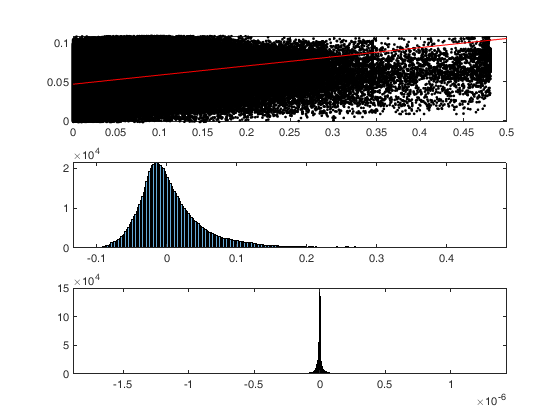

figure; 
subplot(3,1,1)
plot(Tfit.ratio, mdl.Fitted.Response,'.k'); a=lsline; a.Color='r';
subplot(3,1,2);
histogram(Tfit.ratio-mdl.Fitted.Response)
subplot(3,1,3);
histogram((Tfit.ratio-mdl.Fitted.Response).*Tfit.dens_tt./sum(Tfit.dens_tt))

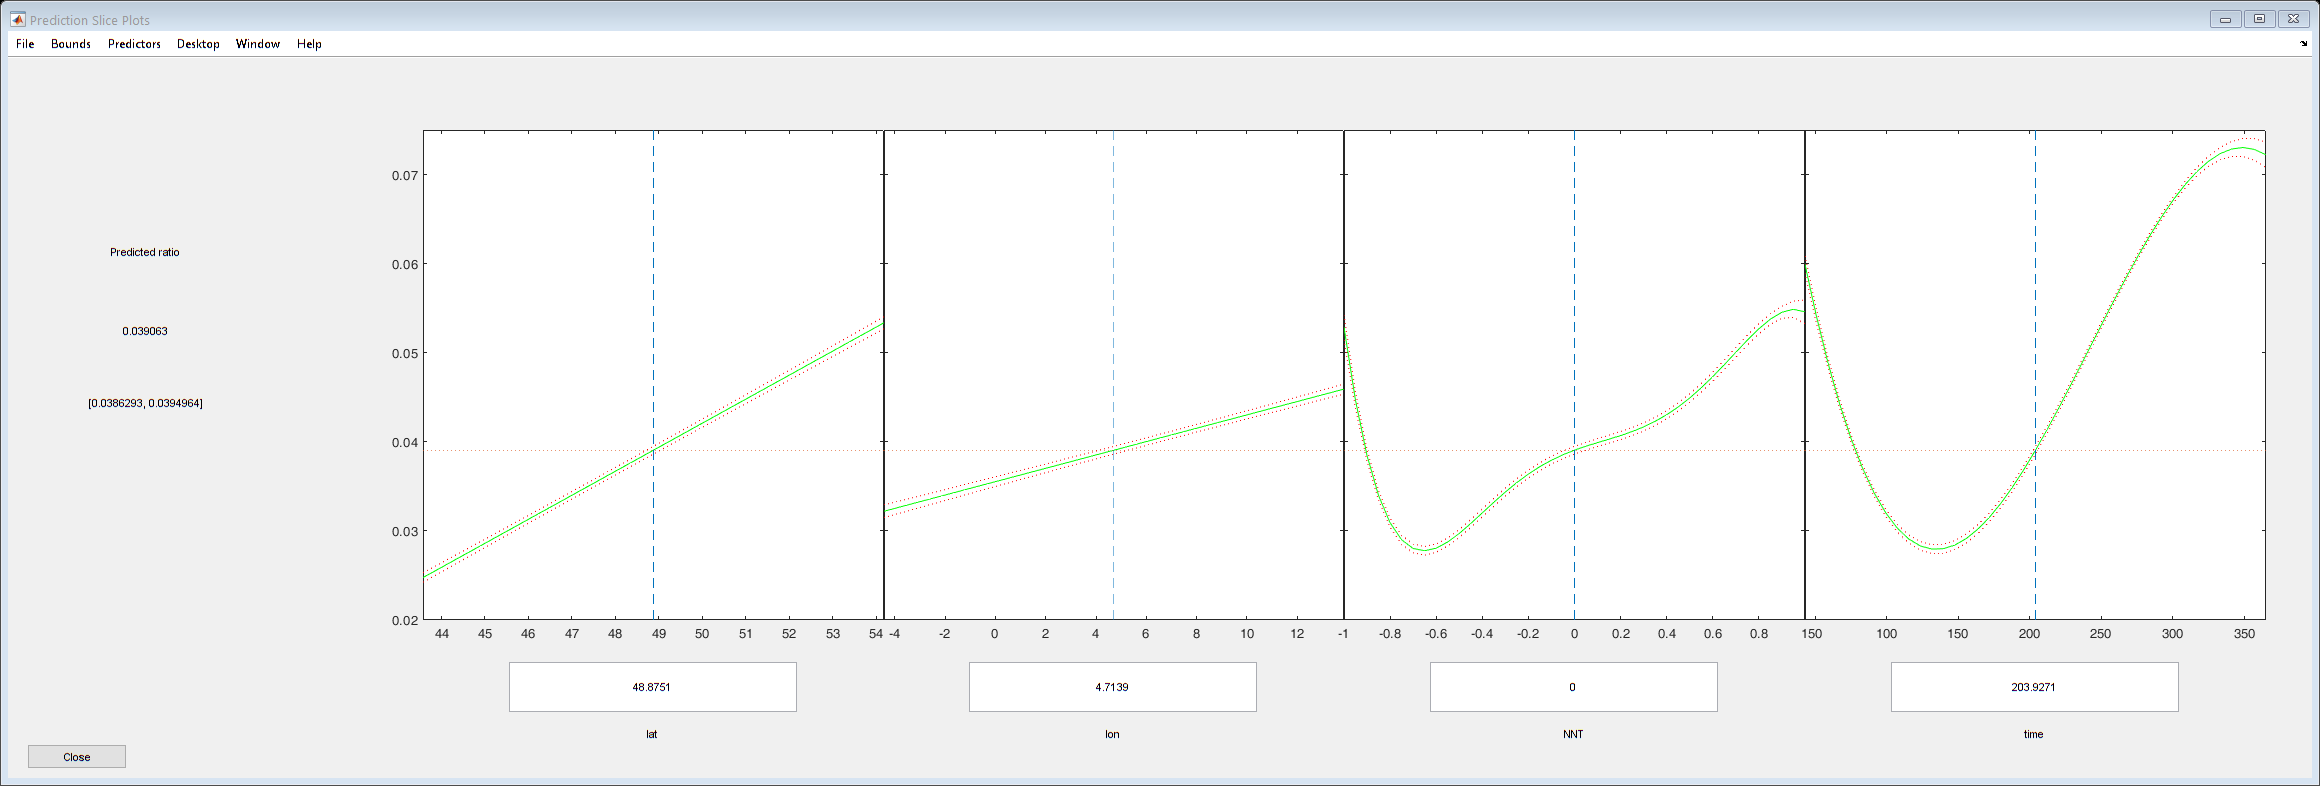

%plotDiagnostics(mdl)
% plotResiduals(mdl)
plotSlice(mdl)

%plotPartialDependence(mdl,'NNT')

## Fit vs Empirical Value 

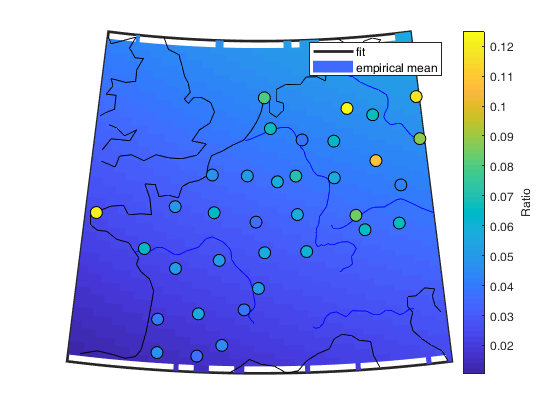

RatioPred = reshape(predict(mdl,[g.lat2D(:) g.lon2D(:) zeros(numel(g.lat2D),1) 182.*ones(numel(g.lat2D),2)]),size(g.lat2D));

load('coastlines.mat');
figure;
hold on; h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
surfm(g.lat2D, g.lon2D, RatioPred) 
plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat], [dc.lon], 80, nanmean(ratio),'filled','MarkerEdgeColor','k'); 
c=colorbar;c.Label.String='Ratio'; legend('fit','empirical mean')

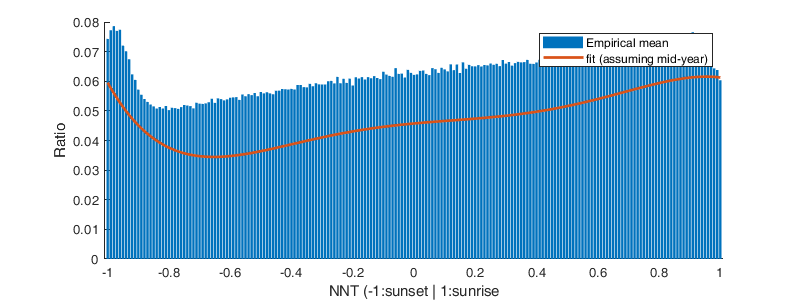

[G,G_NNT]=findgroups(round(Tfit.NNT,2));
[G_ratio] = splitapply(@nanmean,Tfit.ratio,G);
RatioPred2 = predict(mdl,[[49 6].*ones(numel(G_NNT),2) G_NNT mean(Tfit.time).*ones(numel(G_NNT),2)]);

figure('position',[0 0 800 300]); hold on;
bar(G_NNT,G_ratio,'DisplayName','Empirical mean')
plot(G_NNT,RatioPred2,'linewidth',2,'DisplayName','fit (assuming mid-year)'); 
xlabel('NNT (-1:sunset | 1:sunrise');ylabel('Ratio');legend()

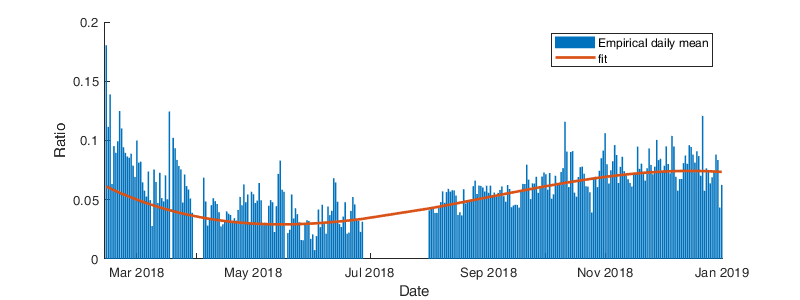

[G,G_time]=findgroups(round(Tfit.time,0));
[G_ratio] = splitapply(@nanmean,Tfit.ratio,G);
RatioPred3 = predict(mdl,[[49 6 0].*ones(numel(G_time),3) G_time ones(numel(G_time),1)]);

G_timedate= datetime(datenum(dc(1).time(1))+G_time,'ConvertFrom','datenum');
figure('position',[0 0 800 300]); hold on;
bar(G_timedate,G_ratio,'DisplayName','Empirical daily mean')
plot(G_timedate,RatioPred3,'linewidth',2,'DisplayName','fit')
xlabel('Date'); ylabel('Ratio'); legend()

## Predict on grid

g_ratio = predict(mdl, [repmat(g.lat2D(g.latlonmask),g.nt,1) repmat(g.lon2D(g.latlonmask),g.nt,1) g.NNT(:) repelem(datenum(g.time-dc(1).time(1)),g.nlm,1) ones(numel(g.NNT(:)),1)]);
g_ratio = reshape(g_ratio,size(g.NNT));
g_ratio(g_ratio<0)=0;
g_ratio(g_ratio>1)=1;

Save

save('./data/ratio','g_ratio','windturbine_minheight','windturbine_maxheight')